# dayplotter

clearvars -except xxkg xxkg2 hkg hkg2 dark light darkmulti lightmulti darker %clear variables that aren't giant structures

# single fish

Average amplitude range figure

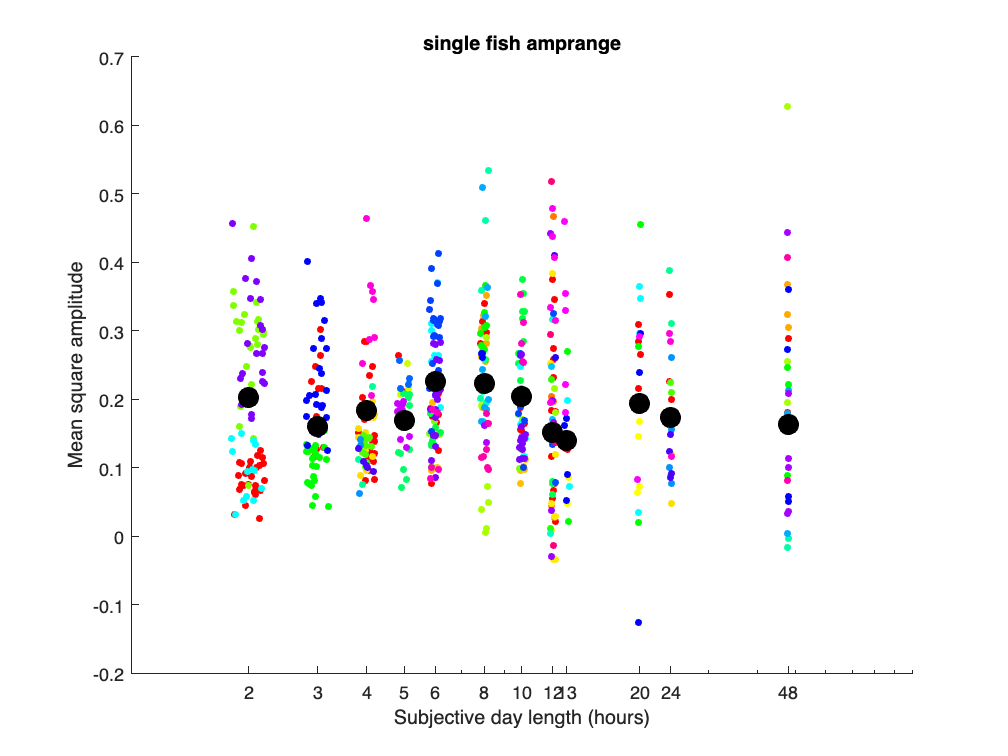

figure(89); clf; title('single fish amprange'); hold on;

    for j = 1:length(dark)

        ld(j,:) = dark(j).ld;
       
        for kk = 1:length([dark(j).fish])
            clrbyfish = hsv(length(dark(j).fish));
            for jj = 1:length(dark(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), dark(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end
   set(gca,'xscale', 'log');%, 'yscale', 'log');
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');

% figure(90); clf; title('singe hour amprange'); hold on;
% 
%  for j = 11
% 
%         ld(j,:) = dark(j).ld;
%        
%         for kk = 1:length([dark(j).fish])
%             clrbyfish = hsv(length(dark(j).fish));
%             for jj = 1:length(dark(j).fish(kk).amprange)
%           %  plot(ld(j,:), dark(j).fish(kk).amprange(jj), clrbyfish(kk,:),'.', 'MarkerSize', 8, 'DisplayName', num2str(kk));
%             scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
%            % label(kk,:) = num2str(kk);
%           
%             end 
%              legend;
%         end
%        % legend;
%         plot(ld(j,:), dark(j).exp.expavgrange, 'k.', 'MarkerSize', 35);
% hold off
% legend show
%  end

Daymean average

figure(317); clf; title('Dark to Light day mean single'); hold on; 
    
    set(gca,'XTick',-2*pi:pi:2*pi);
   % ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.15 0.16]);
    xlim([-pi pi]);
    a = ylim;
clrs = k_colormefriendly;

    fill([-pi -pi 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

    for j = 1:length(dark)
   
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * dark(j).ld);
        p(j) = plot((dark(j).exp.hourtim .* crosshour)-pi, dark(j).exp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end

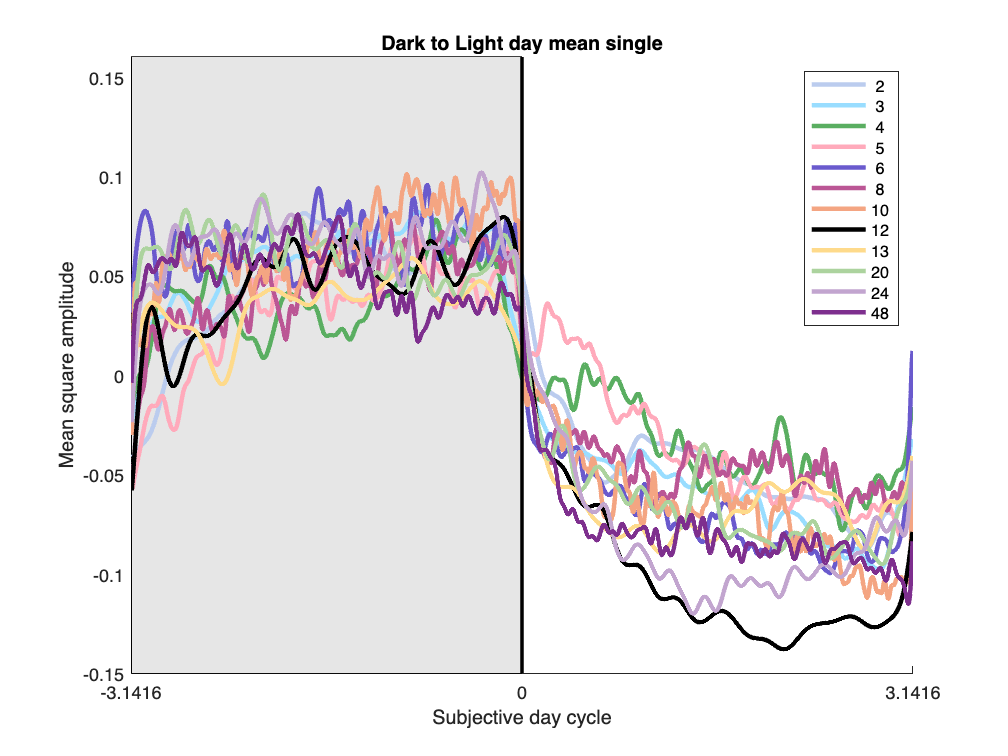

       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

# multifish

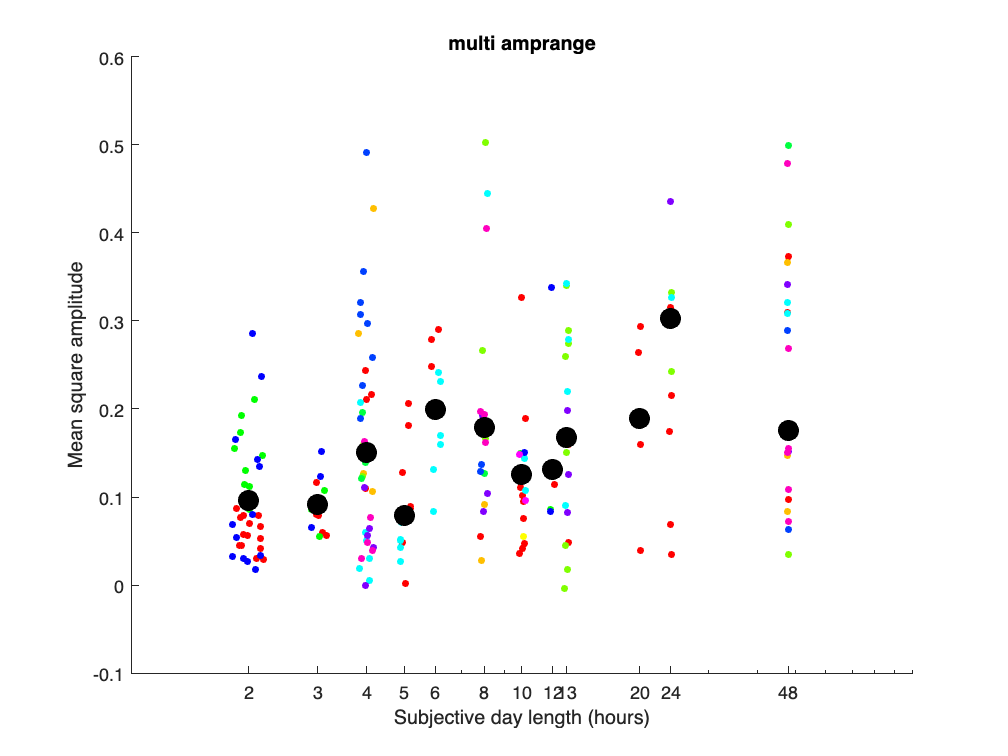

figure(98); clf; title('multi amprange'); hold on;

    for j = 1:length(darkmulti)

        ld(j,:) = darkmulti(j).ld;
       
        for kk = 1:length([darkmulti(j).fish])
            clrbyfish = hsv(length(darkmulti(j).fish));
            for jj = 1:length(darkmulti(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), darkmulti(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
       
        plot(ld(j,:), darkmulti(j).exp.expavgrange, 'k.', 'MarkerSize', 35);

    end
    set(gca,'xscale', 'log');%, 'yscale', 'log');
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');

Daymean average

figure(316); clf; title('Dark to Light day mean multi'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

clrs = k_colormefriendly;

    for j = 1:length(darkmulti)
   
        ld(j,:) = darkmulti(j).ld;
        crosshour = (2*pi) / (2 * darkmulti(j).ld);
        p(j) = plot((darkmulti(j).exp.hourtim .* crosshour)-pi, darkmulti(j).exp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end

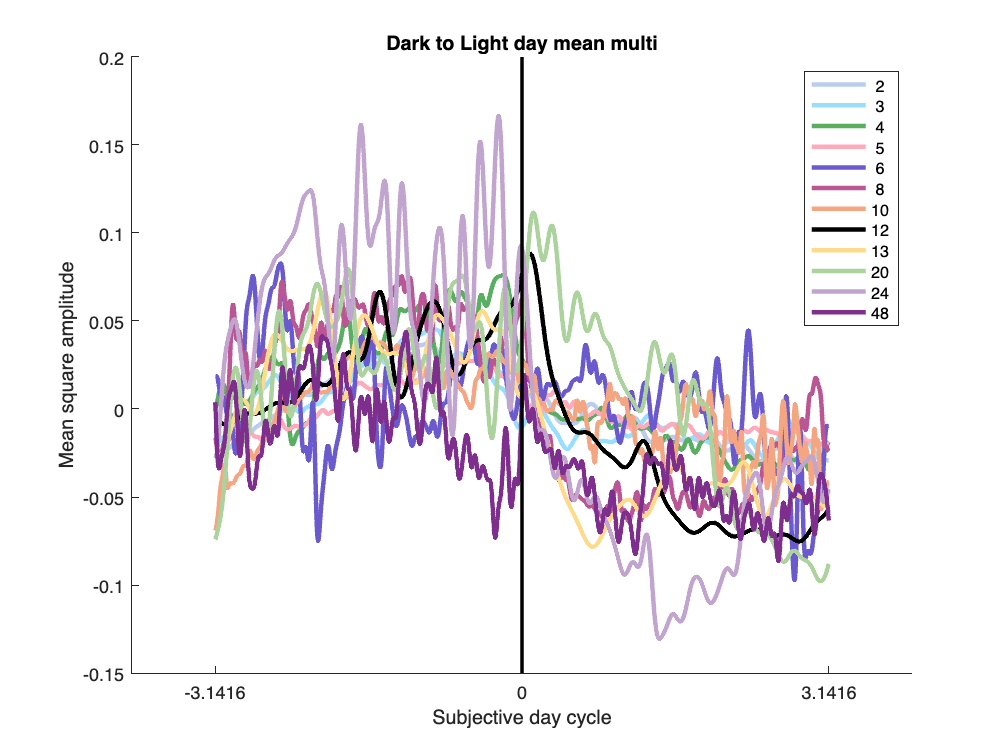

       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');

# Boostrap test for n smoothing

# single fish - multi will be the same

Average amplitude range figure

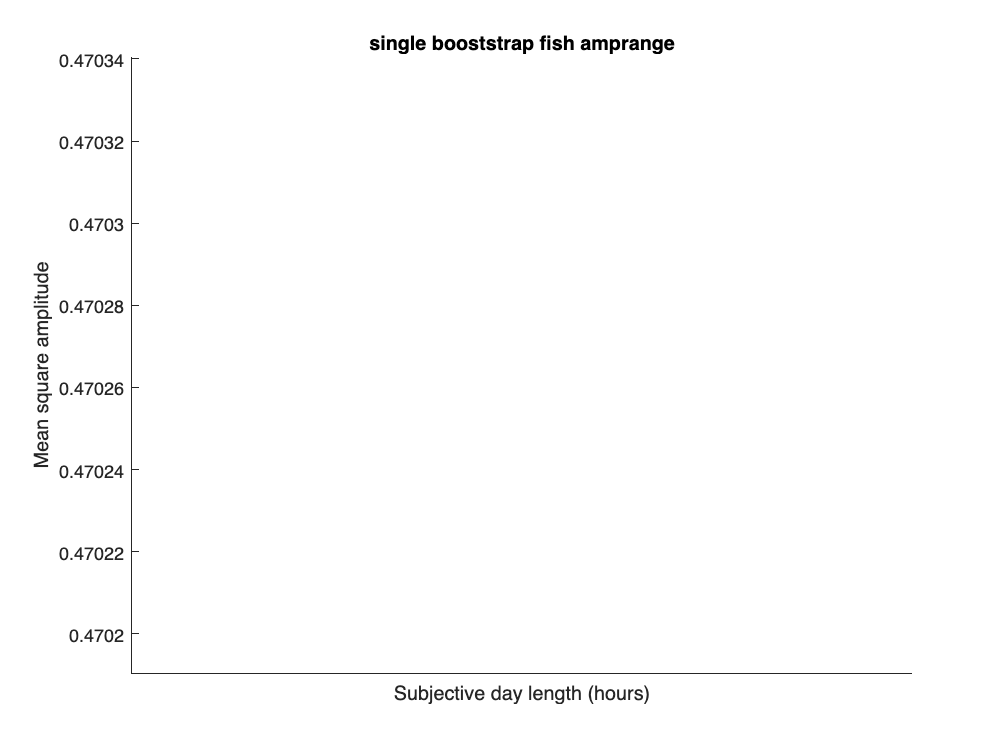

figure(878); clf; title('single booststrap fish amprange'); hold on;

    for j = 1:length(darker)%loop through experiment hours

        ld(j,:) = darker(j).ld;

        fish = unique(darker(j).singlefish.fish');
        clrbyfish = hsv(length(fish));
  
            
            for jj = 1:length(darker(j).singlefish.singlesomeamprange)
                    clridx(jj) = find(darker(j).singlefish.fish(jj) == fish);
                 scatter(ld(j,:), darker(j).singlefish.singlesomeamprange(jj), 15, clrbyfish(clridx(jj),:),'filled','jitter', 'on', 'jitterAmount', 0.2);

            end
       
        plot(ld(j,:), darker(j).singexp.expavgrange, 'k.', 'MarkerSize', 35);

    end
   set(gca,'xscale', 'log');%, 'yscale', 'log');
   xticks([2 3 4 5 6 8 10 12 13 20 24 48]);
   xlabel('Subjective day length (hours)');
   ylabel('Mean square amplitude');

Daymean average

figure(317); clf; title('Dark to Light day mean single bootstrap'); hold on; 
    
    set(gca,'XTick',-2*pi:pi:2*pi);
   % ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    ylim([-0.2 0.4]);
    xlim([-pi pi]);
    a = ylim;
clrs = k_colormefriendly;

    fill([-pi -pi 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

    for j = 1:length(darker)
   
        ld(j,:) = darker(j).ld;
        crosshour = (2*pi) / (2 * darker(j).ld);
        p(j) = plot((darker(j).singexp.hourtim .* crosshour)-pi, darker(j).singexp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
         legend(num2str(ld)); 
        legend('AutoUpdate', 'off'); 
    
    end

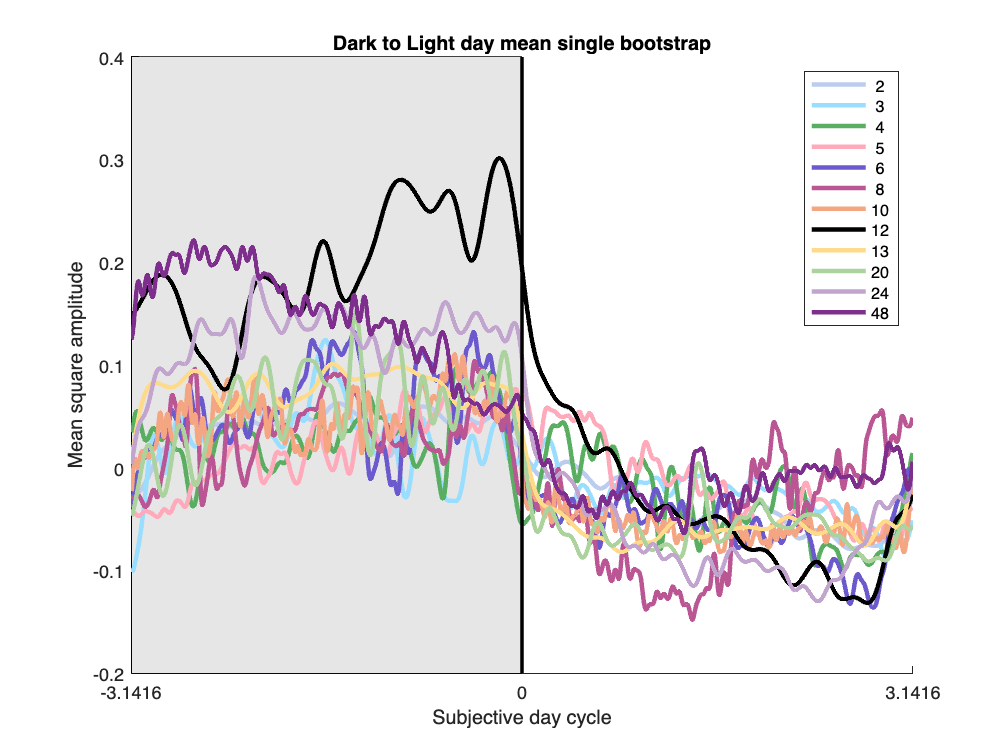

       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');